# 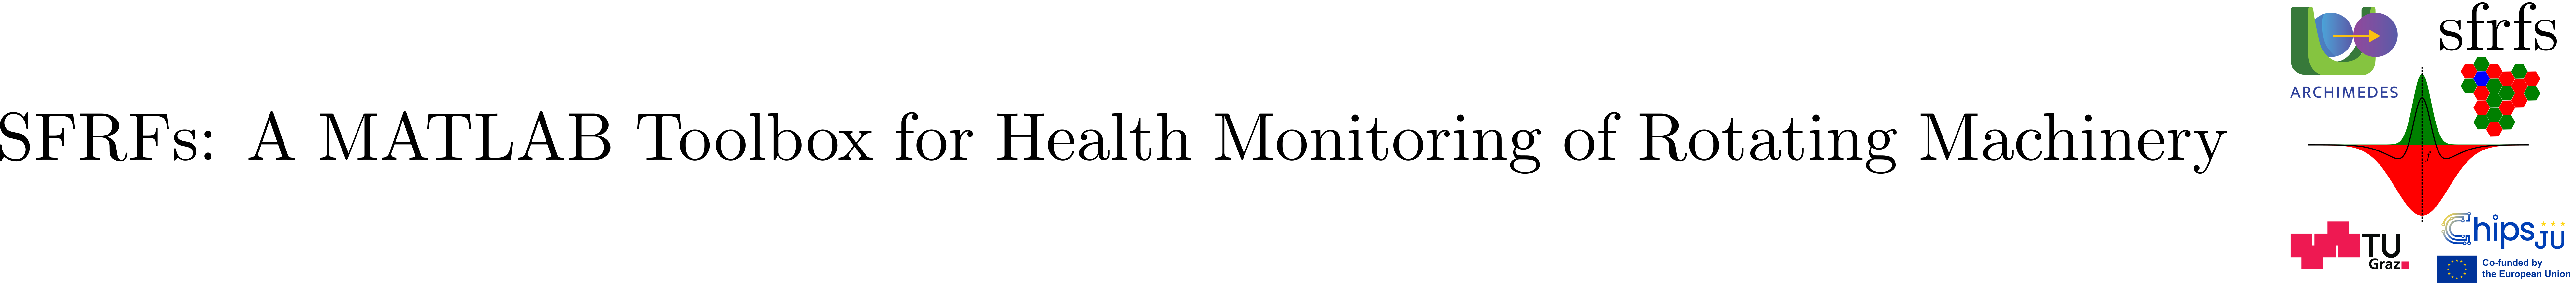

# SFRFsParameters (Abstract)

## Summary

Abstract base class for storing and validating parameters related to Spectral Fault Receptive Fields.

Key features:

- Defines an abstract constant property `faultTypes` for subclasses to specify relevant fault types.

- Provides a comprehensive collection of constant parameter field names representing core SFRF settings such as order, number of sidebands, harmonics, Gaussian mask bandwidths, and inhibition factors.

- Implements a static factory method `createSFRFsParameters` to generate validated parameter structs with sensible defaults and input validation.

- Designed to be extended by concrete subclasses which define domain-specific fault parameters.

This class centralizes parameter handling for SFRF computations, promoting consistency and validation across fault type implementations. By its contract, subclasses must specify their fault types, enhancing structural design and ensuring consistency throughout the processing pipeline.

## Description

`SFRFsParameters` is an abstract base class that defines the common parameter structure used to construct Spectral Fault Receptive Fields (SFRFs). The class provides a unified and validated representation of SFRF parameter sets while delegating the definition of available fault types to concrete subclasses. Each subclass specifies its supported fault modes through an abstract constant property, ensuring that parameter groups remain domain-appropriate. The class standardizes the SFRF parameter fields through a set of constant property names, enabling consistent downstream access, validation, and documentation. These parameters describe the receptive-field configuration in the spectral domain, including order, harmonic and sideband counts, Gaussian center and surround masks, and the inhibitory interaction factor. 

`SFRFsParameters` includes a fully implemented static factory method, `createSFRFsParameters`, that constructs parameter structs using named arguments with built-in validation and defaults. This method ensures robust and reproducible parameter creation across all subclasses. Figure 1 depicts the static attributes of the class SFRFsParameters.

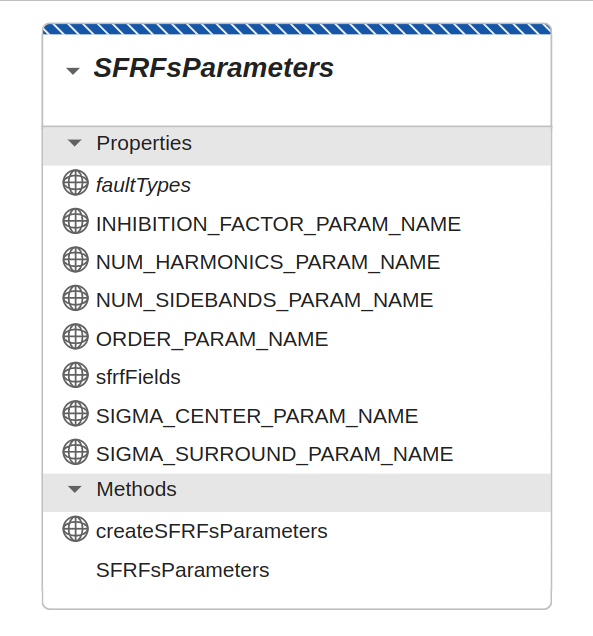

**Figure 1**. Abstract class SFRFsParameters.

### Abstract Constant Properties

### Constant properties

### Static methods

#### Method parameters

The method `createSFRFsParameters(parameter=value,...)` accepts the following arguments:

### Parameters meaning

A formal description of the parameters can be found in Reference [1]. Here we provide a minimal explanation.

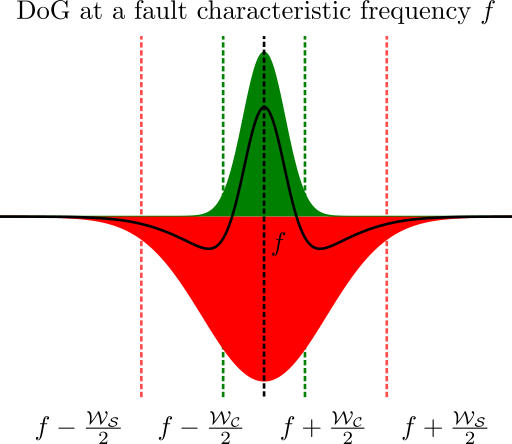

Figure 1. Difference of Gaussians (DoG) shape parameters. 

Figure 1 depicts a difference of Gaussians gain profile obtained from two Gaussian profiles of different sign.  The continuous line function is an example of what we call a **receptive field gain function** (RFGF). The positive Gaussian (green profile) is called the **center**, the negative Gaussian (red profile) is called the **surround**. The central frequency of both center and surround coincide with a given characteristic frequency or frequency of interest. RFGFs can include more than one monitoring frequency by means of specifying the **number of harmonics** and the **number of sidebands**.

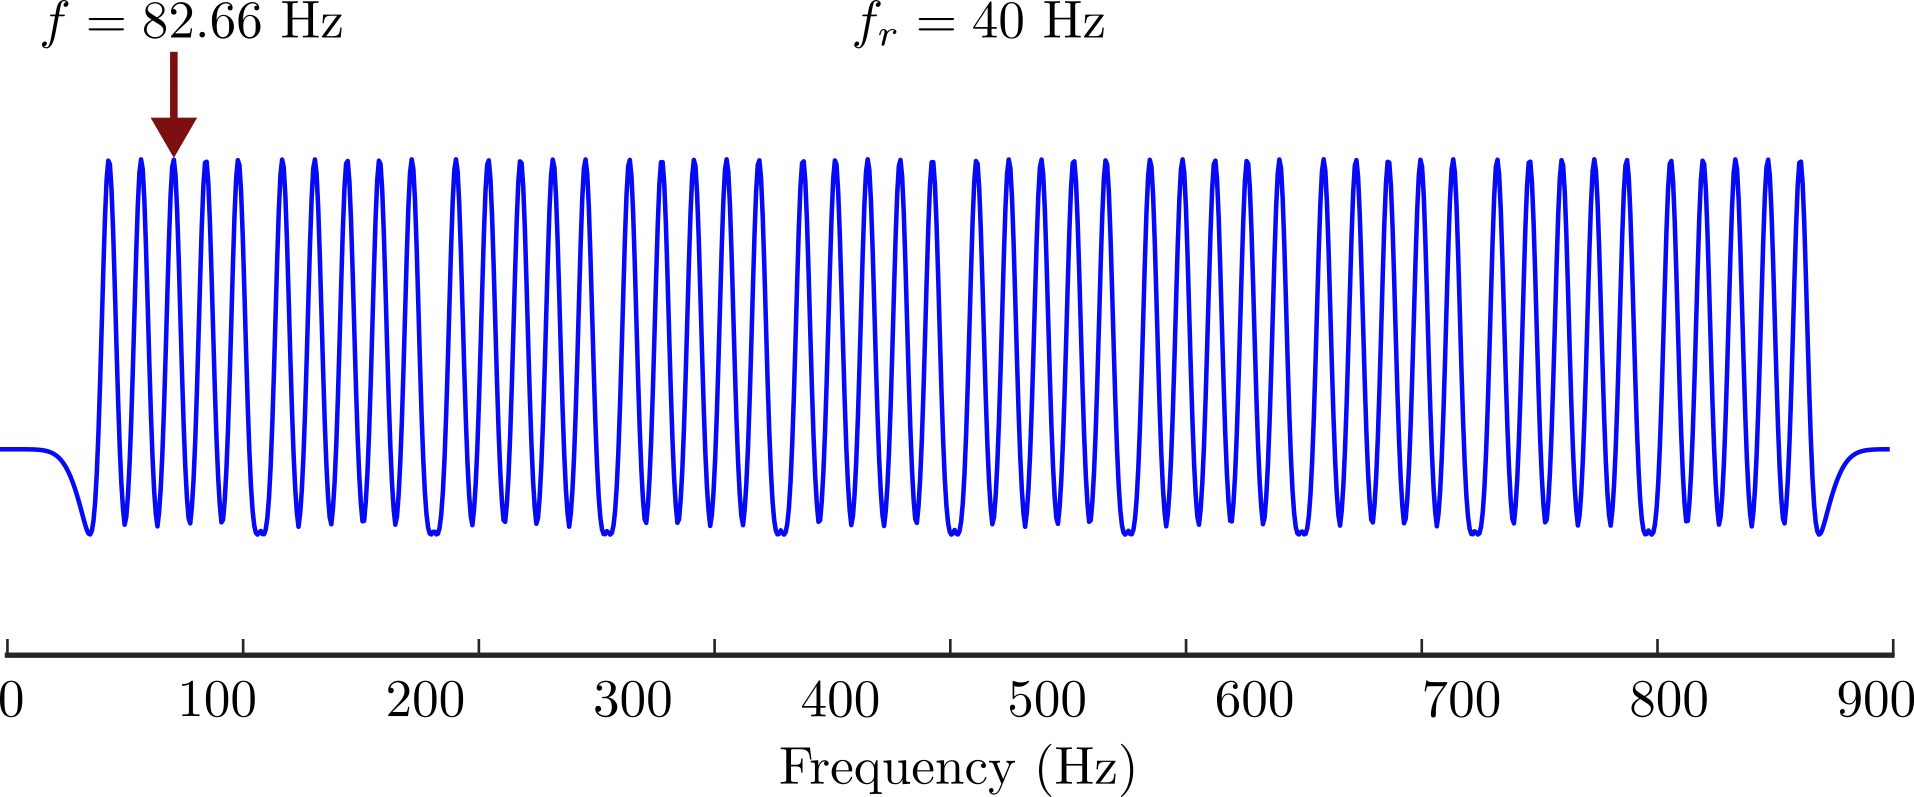

**Figure 2**. Receptive Field Gain Function (RFGF) example. 

Figure 2 plots the RFGF for a concrete example. The frequency of interest $f$ corresponds with the Ball Pass Frequency (BPF) of a heavy duty bearing [LDK UER204](https://www.ldk-bearings.com/products/uer2-insert-bearing-chrome-steel-bearing/) (see [ParametersRollingBearing](matlab:open('./ParametersRollingBearings.mlx')), and Reference [2]); other parameters correspond with those that are associated with this class and are:  

## Example

Being abstract we cannot instantiate this class, for a complete example see [SFRFsParametersRollingBearings](matlab:open('./SFRFsParametersRollingBearings.m')). For the provided example we can nevertheless instantiate a struct descriptor as follows.

% SFRFs order
order = 3;
% number of sidebands
numSidebands = 2;
% number of harmonics
numHarmonics = 10;
% center bandwith (Hz)
centerBandwith = 4;
% center sigma rule
centerSigmaRule = 2/3;
% center shape parameters
sigmaCenter = [centerBandwith,centerSigmaRule];
% center bandwith (Hz)
surroundBandwith = 3*centerBandwith;
% center sigma rule
surroundSigmaRule = 2/3;
% center shape parameters
sigmaSurround = [surroundBandwith,surroundSigmaRule];
% inhibition factor
inhibitionFactor = 1/3;

% use static method to define the SFRFs parameters
sfrfsParams = SFRFsParameters.createSFRFsParameters(...
    order=order, ...
    numHarmonics=numHarmonics, ...
    numSidebands=numSidebands, ...
    sigmaCenter=sigmaCenter, ...
    sigmaSurround=sigmaSurround, ...
    inhibitionFactor=inhibitionFactor);
disp(sfrfsParams);

               order: 3
        numSidebands: 2
        numHarmonics: 10
         sigmaCenter: [4 0.6667]
       sigmaSurround: [12 0.6667]
    inhibitionFactor: 0.3333



## API documentation

### MATLAB help

help SFRFsParameters

  SFRFsParameters Abstract base class to store and validate Spectral
  Fault Receptive Fields (SFRF) parameters.
 
    Stores validated SFRF parameter sets for different fault types
    having those fault types defined in the concrete extending classes.
 
    Supports:
      - Definition of fault types via an abstract constant property.
      - Creation of SFRF parameter structs using a generic fully 
        implemented static method.
 
  Properties:
    (Concrete subclasses define properties specific to domain.)
 
  Abstract Constant Properties:
    faultTypes - Cell array of fault type names for a given subclass.
 
  Static Methods:
    createSFRFsParameters - Create parameter struct for SFRFs.

    Documentation for SFRFsParameters
       doc SFRFsParameters




### MATLAB documentation

doc SFRFsParameters

Opens the full class documentation in the MATLAB Help Browser, including formatted examples, links to related functions, and extended descriptions.

## Source code

The source of the class can be found in [SFRFsParameters](matlab:open('../../SFRFsParameters.m')).

## Test

A unit test for validations performed by the static method in this class can be found in [TestSFRFsParameters](matlab:open('../../../tests/TestSFRFsParameters.m')).

% execute tests
res = runtests('Spectral Fault Receptive Fields/tests/TestSFRFsParameters');

Running TestSFRFsParameters
...
Done TestSFRFsParameters
__________



% display summary of tests
SFRFsTestUtil.printTestSummary(res,80);

Test Name                                                                        | Result
-----------------------------------------------------------------------------------------
TestSFRFsParameters/testDefaultParameters                                        | Passed
TestSFRFsParameters/testCustomParameters                                         | Passed
TestSFRFsParameters/testValidationErrors                                         | Passed



## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).

## References

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis. In 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025). Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1-9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025) [DOI:10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9).

- [2] Biao Wang, Yaguo Lei, Naipeng Li, Ningbo Li, “A Hybrid Prognostics Approach for Estimating Remaining Useful Life of Rolling Element Bearings”, IEEE Transactions on Reliability, pp. 1-12, 2018. [DOI: 10.1109/TR.2018.2882682](https://doi.org/10.1109/TR.2018.2882682).